% close all;
% clear all;
% 
% % 读取音频文件
% [fileName, filePath] = uigetfile('*', '选择音频文件');
% audioFile = fullfile(filePath, fileName);
% [y, fs] = audioread(audioFile); % 读取多通道音频文件 
% disp(fs);
% disp(size(y));
% % disp(max(y));
% % disp(min(y));
% y = double(y);
% dt = 1/fs;
% t = (0:length(y)-1)/fs;
% t = transpose(t);
% plot(t, y)
% grid on;
% xlabel('Time(s)');
% ylabel('Amplitude');
close all;
clear all;

% 读取音频文件
[fileName, filePath] = uigetfile('*', '选择音频文件');
audioFile = fullfile(filePath, fileName);
[y, fs] = audioread(audioFile); % 读取多通道音频文件 
disp(fs);

       51200



disp(size(y));

      768000           2



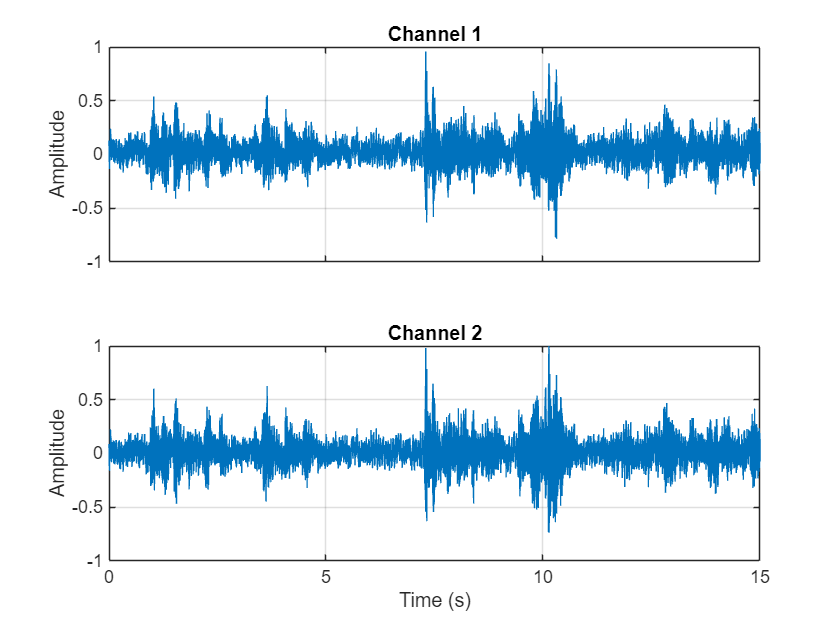


y = double(y);
dt = 1/fs;
t = (0:length(y)-1)/fs;
t = transpose(t);

numChannels = size(y, 2); % 通道数

figure;

% 创建对应通道数的子图
ax = gobjects(numChannels,1); % 预分配Axes对象数组
for ch = 1:numChannels
    ax(ch) = subplot(numChannels, 1, ch);
    plot(t, y(:, ch));
    grid on;
    ylabel(['Amplitude']);
    if ch == numChannels
        xlabel('Time (s)');
    else
        set(gca, 'XTickLabel', []); % 非最后一个子图隐藏x轴标签，保持整洁
    end
    title(['Channel ' num2str(ch)]);
end

% 同步所有子图的x轴，使其对齐
linkaxes(ax, 'x');


% 显示第一个通道的平均幅度值
disp(['Average value of amplitude (channel 1): ', num2str(mean(y(:,1)))]);

Average value of amplitude (channel 1): 0.030777



disp(['Average value of amplitude: ', num2str(mean(y(:,1)))]);

Average value of amplitude: 0.030777



% %% ---------------------------------------------------
% 
% % 2. 计算包络线
% analytic_signal = hilbert(y); % 计算希尔伯特变换
% envelope = abs(analytic_signal); % 取绝对值作为包络线
% 
% % 3. 绘制声波图和包络线
% figure;
% plot(t, y, 'b'); % 绘制原始信号（声波图）
% hold on;
% plot(t, envelope, 'r', 'LineWidth', 1.5); % 绘制包络线
% xlabel('时间 (秒)');
% ylabel('幅度');
% title('声波图及其包络线');
% legend('原始信号', '包络线');
% grid on;
% hold off;

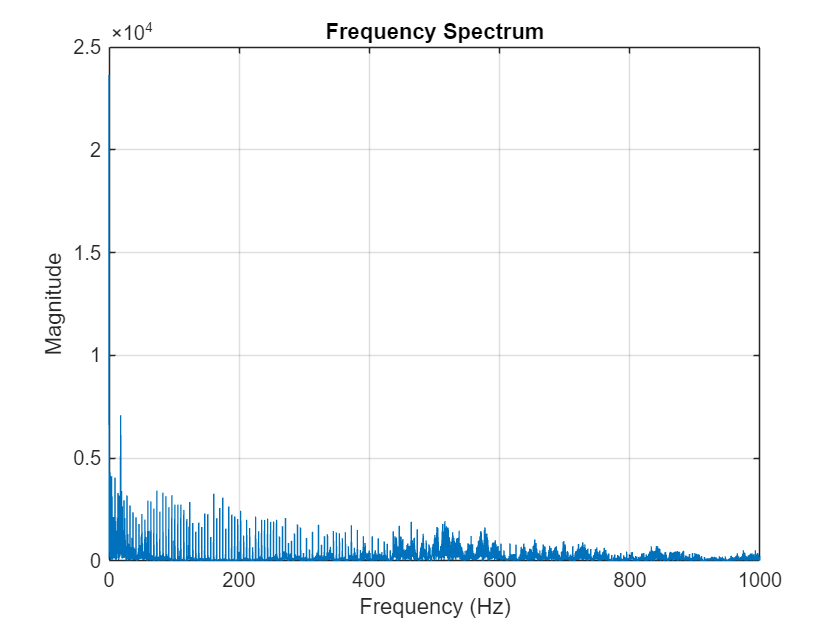


% 应用FFT
N = length(y); % 音频信号的长度
fftResult = fft(y); % 计算FFT

% 计算频率轴
frequencies = (0:N-1)*(fs/N); % 频率范围
magnitude = abs(fftResult); % 幅度谱

% 绘制频谱图
figure;
plot(frequencies(1:N/2), magnitude(1:N/2)); % 只绘制正频率部分
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% 可选：设置x轴范围（例如0到2000Hz）
xlim([0 1000]);

% ylim([0 4000])

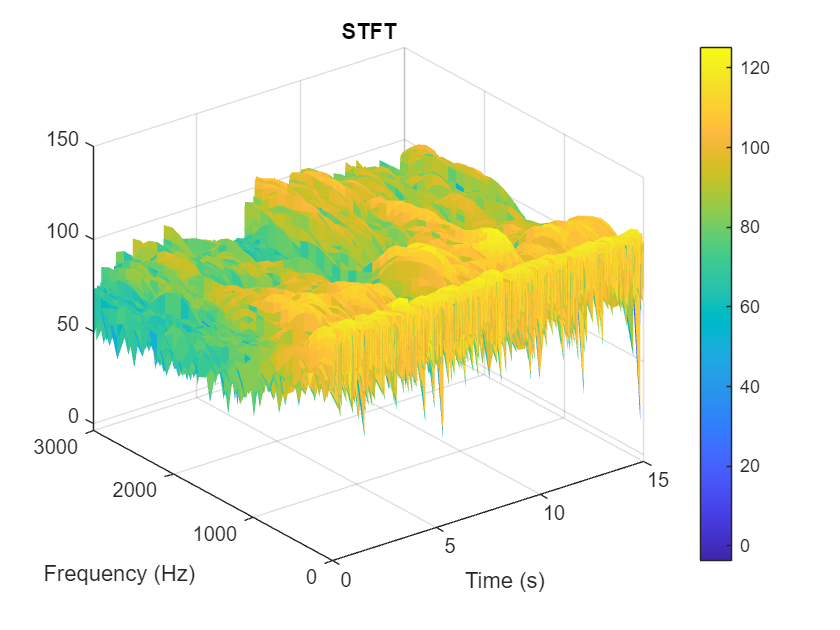


signal = y(:,1);
window = hamming(256); % Hamming窗
noverlap = 128; % 重叠样本数
nfft = 512; % FFT点数
[s, f, t] = stft(signal, fs, 'Window', window, 'OverlapLength', noverlap, 'FFTLength', nfft);

% % 使用均方根（RMS）作为信号强度计算分贝
% rms_values = sqrt(mean(abs(s(:,:,1)).^2, 1)); % 计算每个时间帧的RMS

% 使用20 µPa作为参考值
reference_pressure = 20e-6; % 20 µPa

% % 将RMS转换为dB
% db_values = 20 * log10(rms_values / reference_pressure);

% 绘制频谱图
figure;
% surf(t, f, 10 * log10(abs(s)), 'EdgeColor', 'none');
surf(t, f, 20 * log10(abs(s)/reference_pressure), 'EdgeColor', 'none');

axis xy; 
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT');
ylim([0 3000])
colorbar;

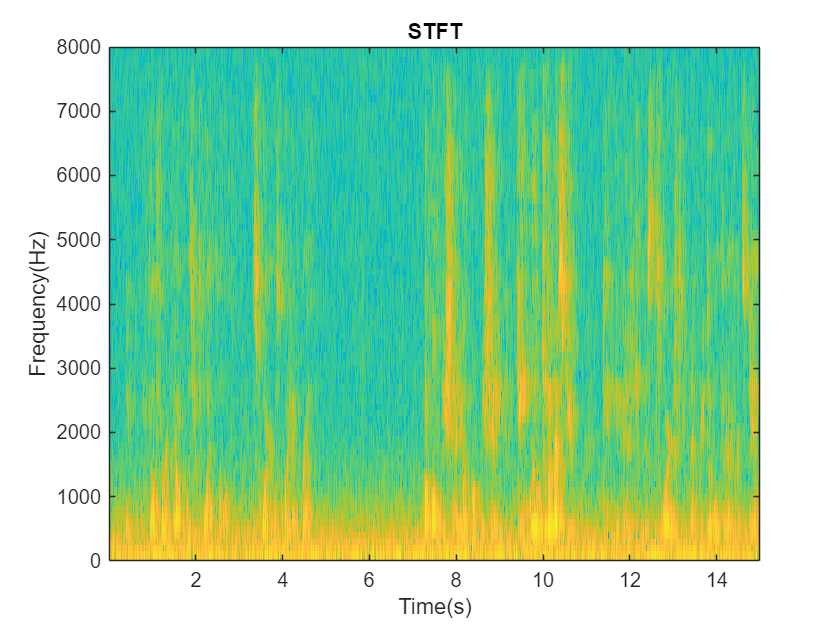


figure;
imagesc(t, f, 20 * log10(abs(s)/reference_pressure) );
% imagesc(t, f, (abs(s(:, :, 1))));
axis xy; 
xlabel('Time(s)');
ylabel('Frequency(Hz)');
ylim([0 8000]);
title('STFT');

% colorbar;
% figure;
% % 原始数据保持线性坐标
% imagesc(t, f, 20*log10(abs(s)/reference_pressure)); 
% axis xy;
% xlabel('Time(s)');
% ylabel('Frequency(Hz)');
% title('STFT');
% colorbar;
% 
% % 设置对数刻度与标签
% set(gca, 'YScale', 'log')       % 启用对数坐标
% ylim([1 8000])                  % 下限需≥1，因log(0)未定义
% 
% % 生成log2刻度序列
% exp_min = ceil(log2(min(f(f>0))));
% exp_max = floor(log2(8000));
% yticks = 2.^(exp_min:exp_max);
% 
% % 设置刻度位置与标签
% set(gca, 'YTick', yticks)
% set(gca, 'YTickLabel', arrayfun(@(x) sprintf('2^{%d}', log2(x)), yticks, 'UniformOutput', false))


% %% ---------------------- SNR Over Time different band pass
% % 设定参数
% signal = y(:,1);
% window_size = 0.01*fs; % 窗口大小
% hop_size = 0.01*fs;     % 重叠步长
% % noise_power = mean(signal(length(signal)-window_size:length(signal)-1).^2); % 基于最后一小段假设整个信号的噪声功率
% % noise_power = estimateNoisePSD_MinStat(signal, fs); % 基于最后一小段假设整个信号的噪声功率
% 
% % 频带定义
% bands_low = [125, 250, 500, 1000, 2000, 4000]; 
% bands_high = [250, 500, 1000, 2000, 4000, 8000];
% 
% % 遍历每个频带，计算SNR并绘制图形
% for band_idx = 1:length(bands_low)
% 
%     % 在频带内滤波信号
%     filtered_signal = bandpass(signal, [bands_low(band_idx), bands_high(band_idx)], fs);
% 
%     % 初始化SNR值存储数组
%     snr_values = [];
% 
%     % 计算每个窗口的SNR
%     for i = 1:hop_size:length(signal)-window_size
%         window = filtered_signal(i:i+window_size-1);
%         window_signal_power = mean(window.^2);
%         snr = 10 * log10(window_signal_power / noise_power);
%         snr_values(end+1) = snr;
%     end
% 
%     % 绘制SNR随时间变化的图形
%     time_vector = (0:length(snr_values)-1) * (hop_size / fs); % 时间向量（秒）
% 
%     figure;
%     plot(time_vector, snr_values, 'LineWidth', 0.8);
%     title_string = sprintf('SNR over Time (%.0f Hz ~ %.0f Hz)', bands_low(band_idx), bands_high(band_idx));
%     title(title_string);
%     xlabel('Time (seconds)');
%     ylabel('SNR (dB)');
%     grid on;
% end


% % 设定参数
% signal = y(:,1);
% window_size = round(0.01 * fs); % 窗口大小，单位样本数
% hop_size = round(0.01 * fs);    % 步长
% 
% % 估计噪声功率谱（频率向量长度为 NFFT/2+1）
% noise_psd_mat = estimateNoisePSD_MinStat(signal, fs);
% % 取最后一帧的噪声PSD作为整体噪声估计（也可以用均值或其他策略）
% noise_psd = noise_psd_mat(:, end);
% 
% % 频带定义
% bands_low = [125, 250, 500, 1000, 2000, 4000]; 
% bands_high = [250, 500, 1000, 2000, 4000, 8000];
% 
% % 预设pwelch参数
% NFFT = (length(noise_psd)-1)*2; % 由noise_psd长度反推NFFT
% window = hamming(window_size);
% 
% % 计算频率向量
% freq_vector = linspace(0, fs/2, length(noise_psd));
% 
% % 遍历每个频带，计算SNR并绘制图形
% for band_idx = 1:length(bands_low)
% 
%     % 频带索引范围
%     band_idx_range = find(freq_vector >= bands_low(band_idx) & freq_vector <= bands_high(band_idx));
% 
%     % 带通滤波信号
%     filtered_signal = bandpass(signal, [bands_low(band_idx), bands_high(band_idx)], fs);
% 
%     % 初始化SNR值存储数组
%     snr_values = [];
% 
%     % 逐窗口计算
%     for start_idx = 1:hop_size:(length(filtered_signal) - window_size + 1)
%         segment = filtered_signal(start_idx : start_idx + window_size - 1);
% 
%         % 计算该窗口的PSD
%         [Pxx, f] = pwelch(segment, window, 0, NFFT, fs);
% 
%         % 取对应频带的信号功率（PSD积分）
%         signal_power = mean(Pxx(band_idx_range));
% 
%         % 取对应频带的噪声功率（PSD均值）
%         noise_power_band = mean(noise_psd(band_idx_range));
% 
%         % 计算SNR（dB）
%         snr = 10 * log10(signal_power / noise_power_band);
% 
%         snr_values(end+1) = snr;
%     end
% 
%     % 时间向量（秒）
%     time_vector = (0:length(snr_values)-1) * (hop_size / fs);
% 
%     % 绘图
%     figure;
%     plot(time_vector, snr_values, 'LineWidth', 1.2);
%     title(sprintf('SNR over Time (%.0f Hz ~ %.0f Hz)', bands_low(band_idx), bands_high(band_idx)));
%     xlabel('Time (seconds)');
%     ylabel('SNR (dB)');
%     grid on;
% end

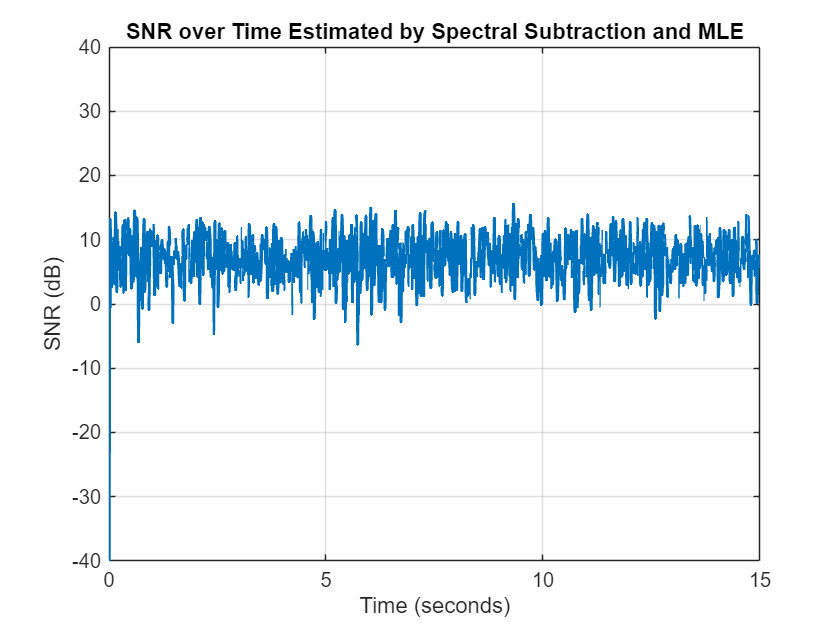

% spectralSubtractionSNR 基于谱减法和最大似然估计的SNR时变估计
%
% 输入：
%   signal - 输入含噪语音信号
%   fs     - 采样率
%
% 输出：
%   snr_time - 每帧估计的SNR（单位dB）

% 参数设置
frame_len = round(0.02*fs);      % 20ms帧长
frame_shift = round(0.01*fs);    % 10ms帧移
NFFT = 2^nextpow2(frame_len);    % FFT点数
win = hamming(frame_len);

% 分帧数
num_frames = floor((length(signal)-frame_len)/frame_shift)+1;

% 初始化噪声功率谱估计（最小统计法简化版）
noise_psd = inf(NFFT/2+1,1);

% 初始化输出
snr_time = zeros(1,num_frames);

% 平滑参数
% alpha = 0.98;  % 频谱平滑因子
alpha = 0.98;  % 频谱平滑因子

for i = 1:num_frames
    idx = (i-1)*frame_shift + (1:frame_len);
    frame = signal(idx).*win;
    
    % 计算功率谱
    X = fft(frame, NFFT);
    magX = abs(X(1:NFFT/2+1));
    powerSpec = magX.^2;
    
    % 更新噪声功率谱估计（最小统计法简化）
    noise_psd = min(noise_psd, powerSpec);
    
    % 平滑噪声功率谱（递归平均）
    noise_psd = alpha*noise_psd + (1-alpha)*powerSpec;
    
    % 谱减法估计纯净语音功率谱
    clean_psd = powerSpec - noise_psd;
    clean_psd(clean_psd < 0) = 0; % 半波整流
    
    % 计算每帧信号与噪声功率（频域积分）
    signal_power = mean(clean_psd);
    noise_power = mean(noise_psd);
    
    % 计算SNR（dB）
    snr_time(i) = 10*log10(signal_power / noise_power + eps);
end

% 绘制SNR随时间变化
time_axis = (0:num_frames-1)*frame_shift/fs;
figure;
plot(time_axis, snr_time, 'LineWidth',1.5);
grid on;
xlabel('Time (seconds)');
ylabel('SNR (dB)');
title('SNR over Time Estimated by Spectral Subtraction and MLE');
ylim([-40 40]);

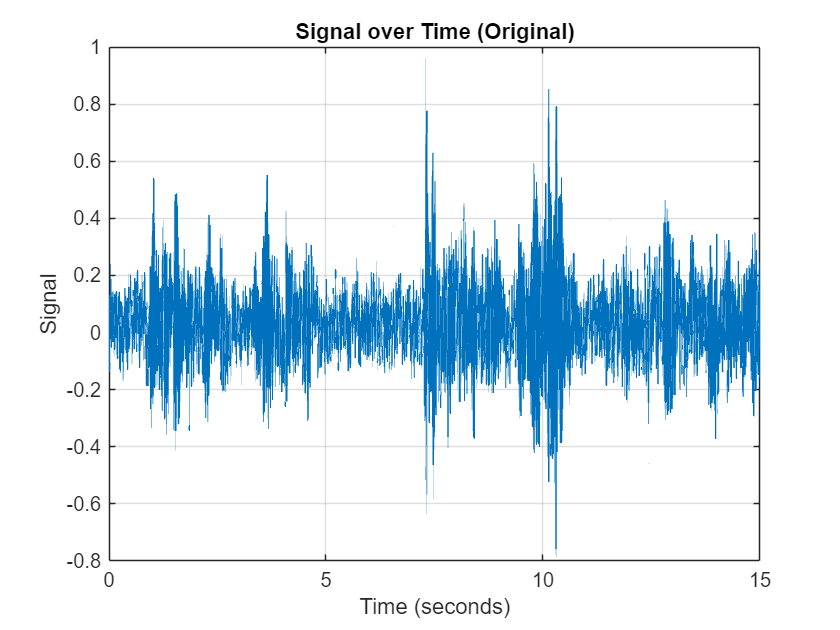

%% ---------------------- Signal Over Time different band pass
% 设定参数
signal = y(:,1);
window_size = 0.01*fs; % 窗口大小
hop_size = 0.01*fs;     % 重叠步长
time_vector = (0:length(signal)-1) / fs; % 时间向量（秒）

figure;
plot(time_vector, signal, 'LineWidth', 0.8);
title_string = sprintf('Signal over Time (Original)');
title(title_string);
xlabel('Time (seconds)');
ylabel('Signal');
grid on;

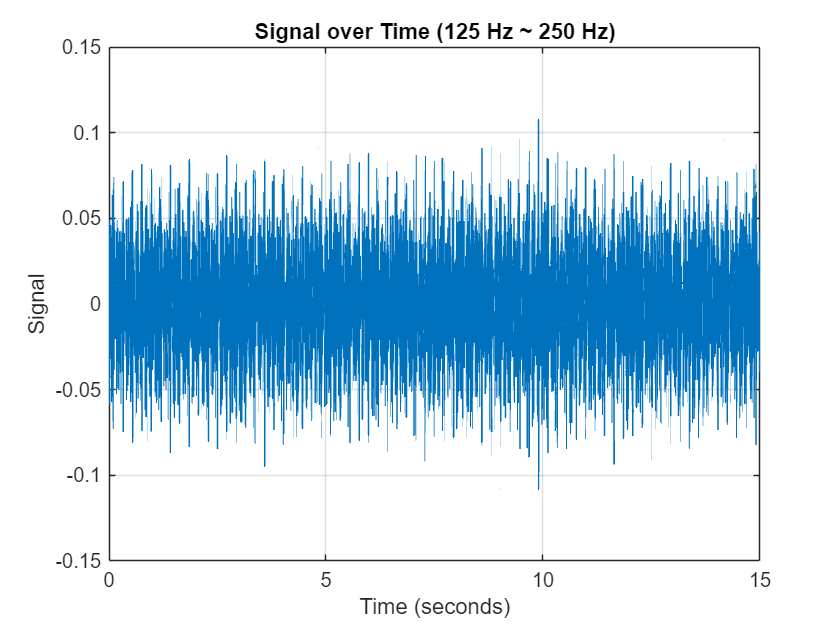

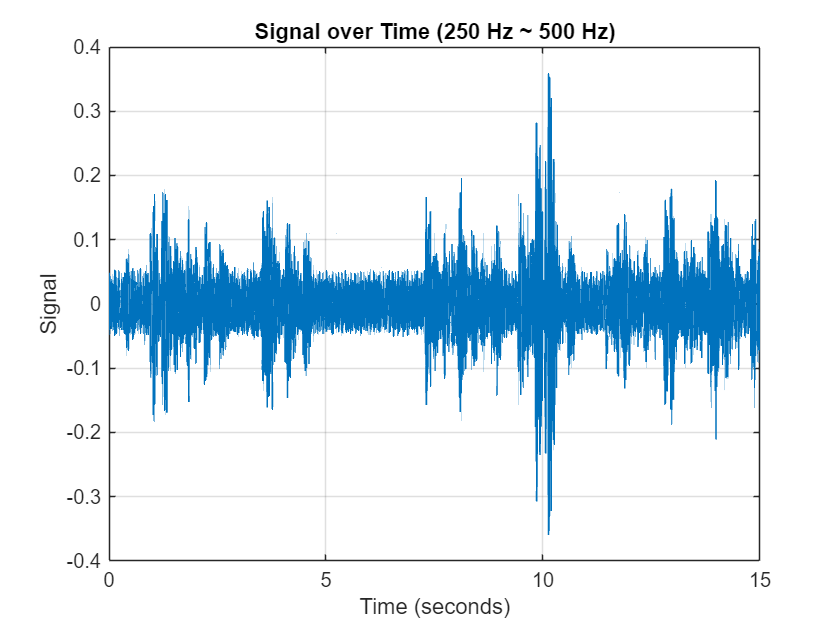

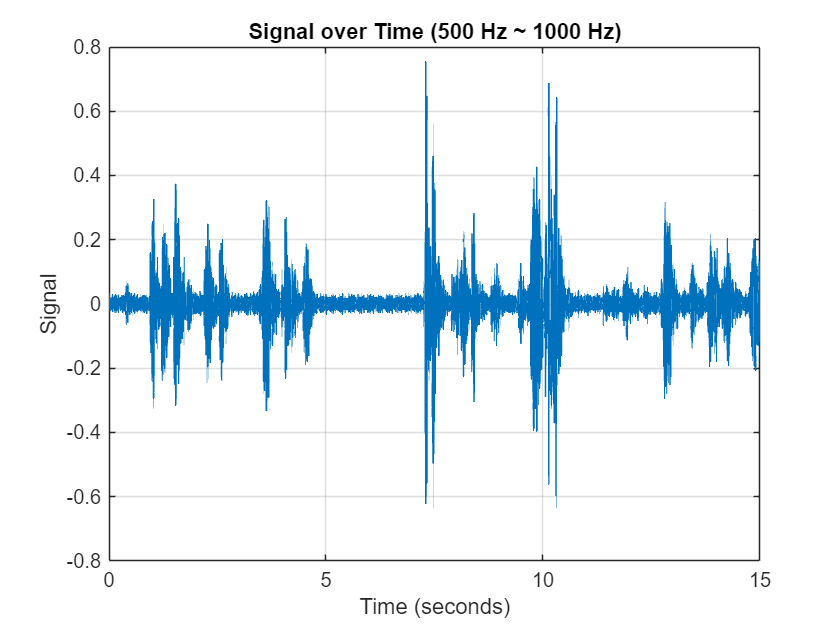

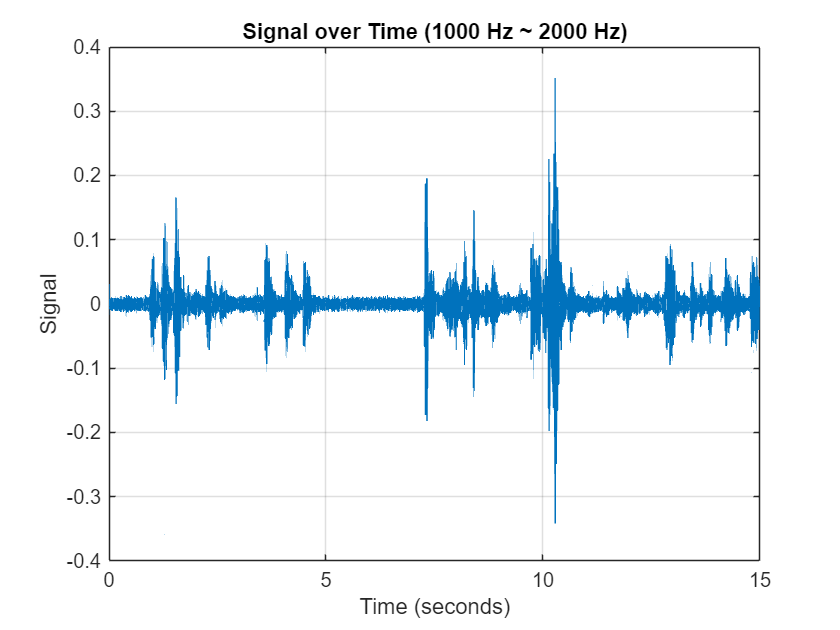

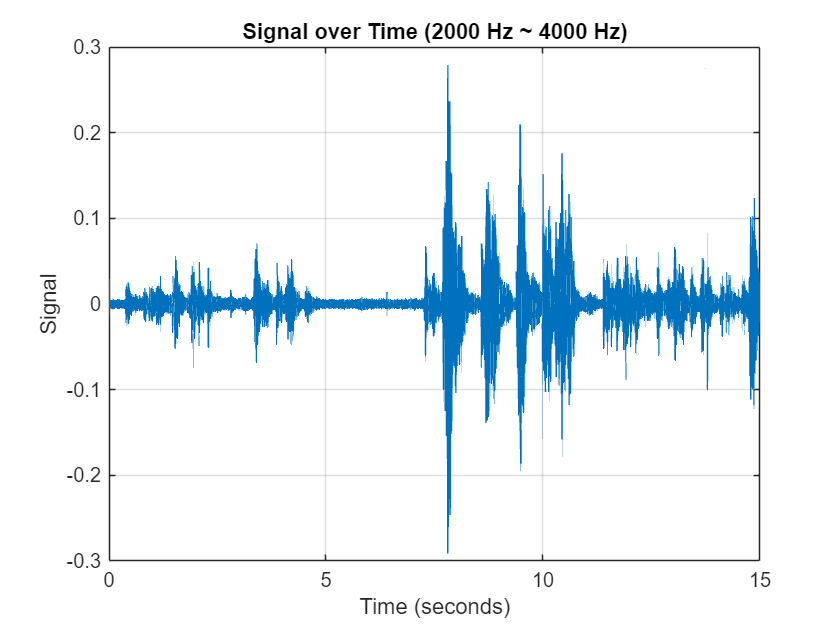

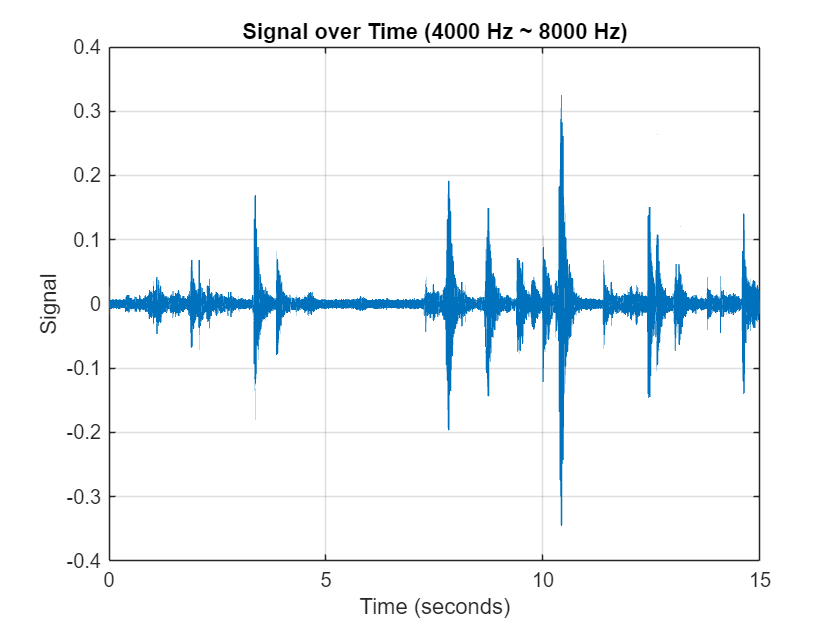

% 频带定义
bands_low = [125, 250, 500, 1000, 2000, 4000]; 
bands_high = [250, 500, 1000, 2000, 4000, 8000];

% 遍历每个频带
for band_idx = 1:length(bands_low)
    band_low = bands_low(band_idx);
    band_high = bands_high(band_idx);
    
    % 在频带内滤波信号
    filtered_signal = bandpass(signal, [bands_low(band_idx), bands_high(band_idx)], fs);
    
    figure;
    plot(time_vector, filtered_signal, 'LineWidth', 0.8);
    title_string = sprintf('Signal over Time (%.0f Hz ~ %.0f Hz)', bands_low(band_idx), bands_high(band_idx));
    title(title_string);
    xlabel('Time (seconds)');
    ylabel('Signal');
    grid on;
end

function noise_psd_track = estimateNoisePSD_MinStat(signal, fs)
    % 输入参数：
    % signal - 输入语音信号（时域）
    % fs - 采样率
    
    % 参数设置
    frame_len = round(0.02 * fs);    % 帧长 20ms
    frame_shift = round(0.01 * fs);  % 帧移 10ms
    NFFT = 2^nextpow2(frame_len);    % FFT点数
    
    % 分帧并加窗
    win = hamming(frame_len);
    num_frames = floor((length(signal)-frame_len)/frame_shift) + 1;
    
    % 初始化变量
    noise_psd = inf(NFFT/2+1,1);    % 噪声功率谱初始设为无穷大
    noise_psd_track = zeros(NFFT/2+1, num_frames); % 记录每帧噪声功率谱估计
    
    alpha = 0.9;  % 平滑因子，控制噪声更新速度
    
    for i = 1:num_frames
        idx = (i-1)*frame_shift + (1:frame_len);
        frame = signal(idx) .* win;
    
        % 计算当前帧功率谱
        X = fft(frame, NFFT);
        Pxx = (abs(X(1:NFFT/2+1))).^2;
    
        % 最小值跟踪更新噪声功率谱
        noise_psd = min(noise_psd, Pxx);  % 取当前噪声估计和当前功率谱的最小值
    
        % 平滑更新（递归平均）
        noise_psd = alpha * noise_psd + (1 - alpha) * Pxx;
    
        % 保存当前噪声功率谱估计
        noise_psd_track(:, i) = noise_psd;
    end
    
    % 结果：
    % noise_psd_track 每列为对应帧的噪声功率谱估计
end